# EE3032-4, Fall, 2019, Dr. Durant's Homework 5, Problem 5.7 with power calculation additions

## (a) Determine if the waveform has dc, even, or odd symmetry.

First, we'll plot the waveform.

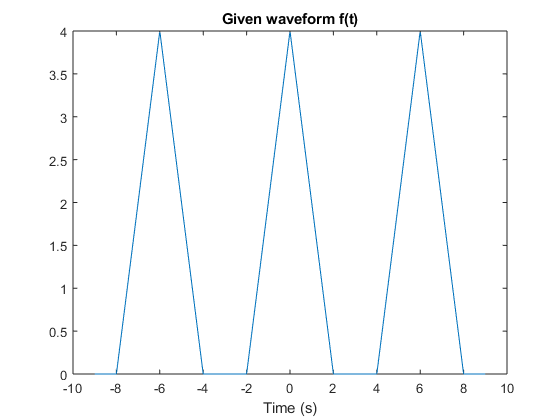

A = 4;
t = linspace(-9,9,1000);
T0 = 6; % seconds
tBase = mod(t,T0); % period is 6, calculate corresponding time on [0,T0) to simplify building the function
f = zeros(size(t)); % correct for region [2,4], etc., where function is 0
f(tBase<2) =    A - (A/2)*tBase(tBase<2); % negative slope portion
f(tBase>4) = -2*A + (A/2)*tBase(tBase>4); % positive slope version, b+mx format
figure,plot(t,f),title('Given waveform f(t)'),xlabel('Time (s)')

We can see from the graph that there is a non-0 DC term (since the average isn't 0), that there is even symmetry (since we can flip the graph from left to right about t=0), and that there is not odd symmetry.

## (b) Obtain its cosine/sine Fourier series representation.

Since there is even symmetry, all the b (sine, odd) terms are 0.

To find the a terms, we apply the integrals in Table 5-3 on page 206.

a0 is the average value of the signal. The area is (1/2)*4*A = 2*A using the area of a triangle and the period is 6, so a0 = 2*A/6 = A/3

a1 can be simplified by taking the integral over the symmetric period [-3,3] and realizing that [0,2] contains area that is doubled on [-2,0] since the product of even functions is even.

f0 = 1/T0;
w0 = 2*pi*f0;
fprintf('The fundamental frequency w0 is %g radians/sec or %g Hz.\n',w0,f0)

The fundamental frequency w0 is 1.0472 radians/sec or 0.166667 Hz.



$$\omega_0=\frac{2\pi}{6}=\frac{\pi}{3}$$


$a_1=\frac{2}{T_0}\int_{T_0}x(t)cos(n\omega_0t)dt$=$\frac{4}{6}\int_0^2(A-\frac{At}{2})cos(\omega_0t)dt$=$\frac{A}{3}\int_0^2(2-t)cos(\omega_0 t)dt$=$\frac{A}{3}[\frac{2}{\omega_0}sin(\omega_0 t)-\frac{t}{\omega_0}sin(\omega_0 t)-(\frac{1}{\omega_0})^2cos(\omega_0 t)]_{t=0}^2$=$\frac{A}{3}[-(\frac{1}{\omega_0})^2cos(2\omega_0)-(-(\frac{1}{\omega_0})^2)]$=$\frac{A}{3\omega_0^2}[-cos(2\omega_0)+1]$=$\frac{3A}{\pi^2}[\frac{1}{2}+1]$=$\frac{3A}{\pi^2}[\frac{3}{2}]$=$\frac{9A}{2\pi^2}$

The form will stay largely the same for n>1. The key difference is that the scaling factor in the antiderivative changes from 3/pi to 3/(n pi).

$a_n=\frac{2}{T_0}\int_{T_0}x(t)cos(n\omega_0t)dt$=$\frac{A}{3}\int_0^2(2-t)cos(n\omega_0 t)dt$=$\frac{A}{3n^2\omega_0^2}[-cos(2n\omega_0)+1]$=$\frac{3A}{n^2\pi^2}[1-cos(\frac{2n\pi}{3})]$

The term in brackets, starting with n=1, is 3/2, 3/2, 0, 3/2, 3/2 0, .... It repeats with period 3 because of the 2\omega_0 term.

Let's skip ahead to part (e) to graphically confirm our answer is correct...

## (e) Use MATLAB or MathScript to plot the waveform using a truncated Fourier series representation with n_{max}=100.

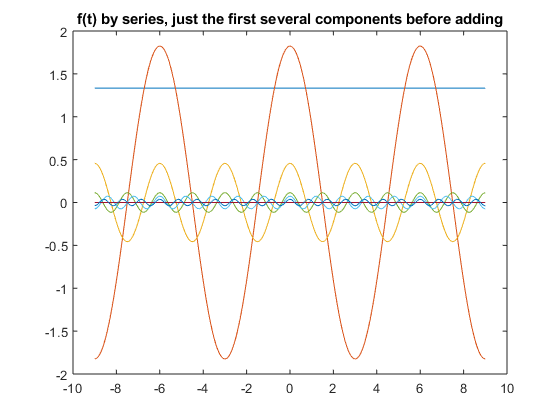

nmax = 7;
n = 0:nmax;
a = 3*A./((n.^2*pi^2)) .* (1-cos(2*n*pi/3)); % for n>=1
a(n==0) = A/3; % a0 is an exception from the pattern
phase = (n'*w0) * t; % outer product, ' is transpose (row->column), rows of results are components; columns are time
components = a' .* cos(phase); % column vector expands across columns of right argument when using .*
figure
plot(t,components(1:min(10,nmax+1),:)), title('f(t) by series, just the first several components before adding')

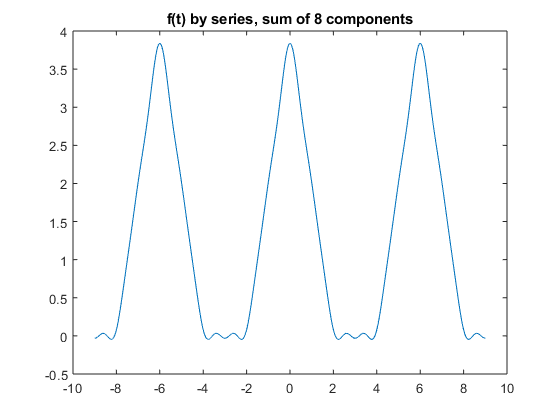

f_ser = sum(components); % sums the rows (components) into a single time series, doc sum to see how to sum other ways
figure
plot(t,f_ser), title(sprintf('f(t) by series, sum of %g components',length(n)))

## (c) Convert the representation to amplitude/phase format and plot the line spectra for the first five non-zero terms.

All the b's are 0, so all the phases must be either 0 or pi; this is true for any even signal. All the b's are non-negative, so the phase is simply 0.

Note: "amplitude" can be positive or negative (so phase can be restricuted to quadrant I and IV if desired), while "magnitude" is never negative, but uses a phase of pi to get the negative of a signal.

We omit the phase plot; it would just show 0 at each n.

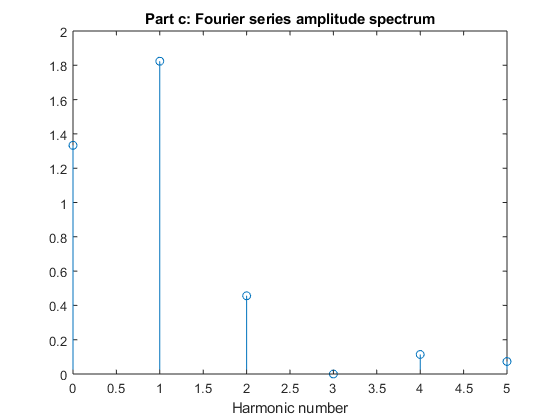

figure
stem(n(1:6), a(1:6))
title('Part c: Fourier series amplitude spectrum')
xlabel('Harmonic number')

## (d) Convert the representation to complex exponential format and plot the line spectra for the first five non-zero terms.

Here you would compute X = (a-jb)/2 for all n >= 1. X0 = a0. X_{-n} = X*_{n}. So, in this case, X are real and non-negative, yielding the same plot as in part (c)

## Additional assigned problems: Also, calculate the power using at least 2 methods: ...

Method 1: directly from f(t)

fp = f(t>=0 & t<T0); % extract 1 period
dt = diff(t(1:2));
Pd = (1/T0) * dt*sum(fp.^2); % Riemann sum for power integral
fprintf('Power using numeric integration is %g.\n', Pd)

Power using numeric integration is 3.55548.


Method 2: using Parseval's relation

in0 = n==0; % mask where n=0
Pp = a(in0).^2 + sum(a(~in0).^2)/2;
fprintf('Power using Parseval is %g.\n', Pp)

Power using Parseval is 3.55466.


Extra method: analytically

Pa = 4*(A^2)/3/T0; % Area under the f^2(t) in 1 period is 4(A^2)/3. Can be found by evaluating the integral analytically.
fprintf('Power analytically is %g.\n', Pa)

Power analytically is 3.55556.
